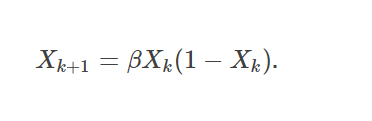

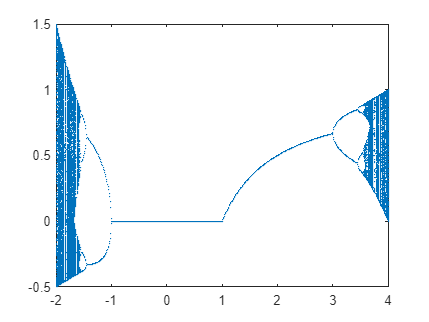

clear all
close all
clc

xplt=[];

for r =-10:0.01:10
r;
%Nuestra población inicial siempre será de 30 %
x_0=0.3;

%Encontrar punto de equilibrio para x+1, con esta r

    for i= 1:2000
        x_1=r*x_0*(1-x_0);
        x_0=x_1;


    end
%Encontramos el punto estabilizado y lo guardamos    
x_estable=x_1;
    for i=1:1000
        x_1=r*x_0*(1-x_0);
        x_0=x_1;

        xplt(1,length(xplt)+1)=r;
        xplt(2,length(xplt)) =x_1;

            if (abs(x_1-x_estable)<0.001)
                break
            end
    end

plot(xplt(1,:), xplt(2,:), ".", 'LineWidth',0.2, 'MarkerSize',0.2 )  

end